%% 5번 문제
clear; clc;

rng('default');

% (a) 
true_temp = 25;
error_std = 0.8;
measurements = true_temp + error_std * randn(10000, 30);

% (b) 
avg_measurements = mean(measurements, 2);

% (c) 
in_range_event = (avg_measurements >= 24.7) & (avg_measurements <= 25.3);

% (d) 
prob_estimated = mean(in_range_event);
fprintf('=== 5번 결과 ===\n');

=== 5번 결과 ===


fprintf('30개 센서 평균이 실제 온도 0.3도 이내일 확률: %.2f%%\n', prob_estimated * 100);

30개 센서 평균이 실제 온도 0.3도 이내일 확률: 96.12%



% (e) 
single_sensor = measurements(:, 1)

single_sensor =    25.4301
   26.4671
   23.1929
   25.6897
   25.2550
   23.9538
   24.6531
   25.2741
   27.8627
   27.2155
   23.9201
   27.4279
   25.5803
   24.9496
   25.5718


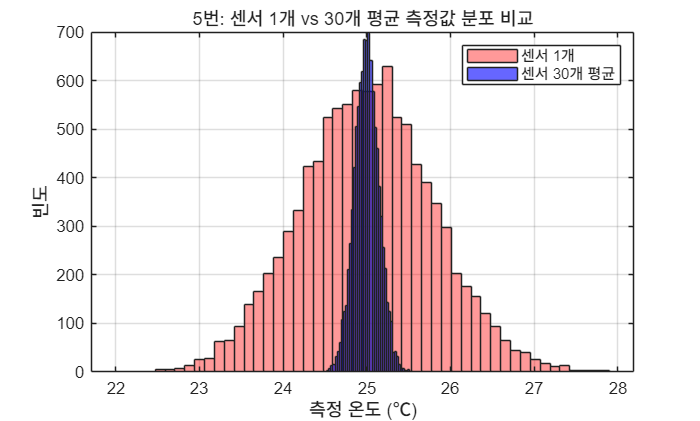


figure(6);
histogram(single_sensor, 50, 'FaceColor', 'r', 'FaceAlpha', 0.4, 'DisplayName', '센서 1개');
hold on;
histogram(avg_measurements, 50, 'FaceColor', 'b', 'FaceAlpha', 0.6, 'DisplayName', '센서 30개 평균');
hold off;
title('5번: 센서 1개 vs 30개 평균 측정값 분포 비교');
xlabel('측정 온도 (℃)');
ylabel('빈도');
legend('show');
grid on;